Set up environment necessary for plots

load('LIMO_output_Tap/clustering_output.mat', 'mask', 'cluster_p', 'one_sample');
load('LIMO_output_Tap/ALL_LIMO_INFO.mat', 'LIMOs');
load('LIMO_output_Tap/inter_tap_intervals.mat', "inter_tap_intervals")


event_names = {'FS_event', 'Tap'};
epoch_size = [-3, 0.5]; % In seconds
electrodes = [1, 2, 6, 10, 16];

inter_tap_intervals = inter_tap_intervals(mod(1:size(inter_tap_intervals, 2), 2) ~= 0);

betas = extract_betas(LIMOs);
betas_names = {'k_{t-1}', 'k_{t+1}', 'Bias'};

## Figure 1

Joint inter-tap-interval distributions

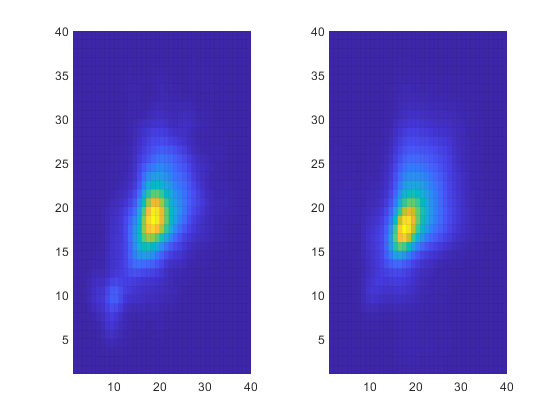

nbins = 50;

figure;
tiledlayout(1, 2);

% Single JID plot
jid_single = PlottingFunctions.iti2JID(inter_tap_intervals{1}', 'Bins', nbins);

nexttile;
jid_plot_single = pcolor(jid_single);
jid_plot_single.EdgeAlpha = 0.05;

% Average JID plot
jid_multi = zeros(nbins, nbins, size(betas, 4));

for ppt = 1:size(jid_multi, 3)
    jid_multi(:, :, ppt) = PlottingFunctions.iti2JID(inter_tap_intervals{ppt}', 'Bins', nbins);
end

jid_average = mean(jid_multi, 3);
nexttile;
jid_plot_avg = pcolor(jid_average);
jid_plot_avg.EdgeAlpha = 0.05;

# Beta plots

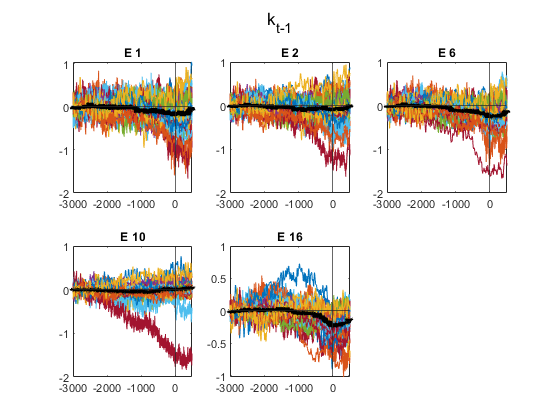

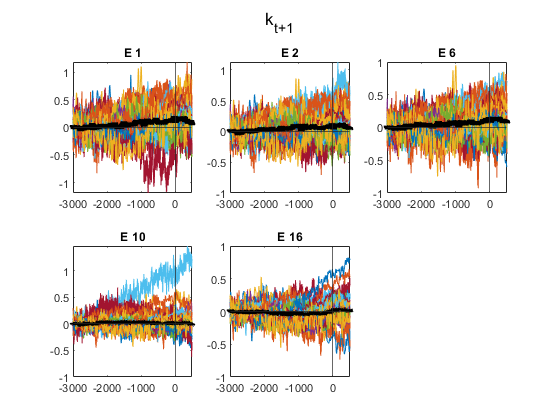

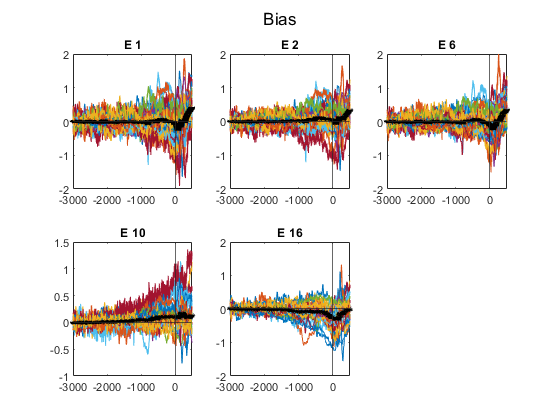

if ~exist('electrodes', 'var') || isempty(electrodes)
    electrodes = 1:size(betas, 1);
end

if ~exist('epoch_size', 'var')
    epoch_size = [0, size(betas, 2)] / 1000;
end

if ~exist('use_trimmed_mean', 'var')
    use_trimmed_mean = true;
end

for beta = 1:size(betas, 3)
    figure;
    sgtitle(betas_names{beta});
    p = numSubplots(length(electrodes));
    
    for electrode_index = 1:length(electrodes)
        subplot(p(1), p(2), electrode_index);
        plot(epoch_size(1) * 1000 + 1:epoch_size(2) * 1000, squeeze(betas(electrodes(electrode_index), :, beta, :)));
        hold on;
        
        % Add mean line
        
        if use_trimmed_mean
            electrode_values = squeeze(betas(electrodes(electrode_index), :, beta, :));
            electrode_values = sort(electrode_values, 2);
            mean_indices = floor(size(electrode_values, 2) * 0.1):ceil(size(electrode_values, 2) * 0.9);
            mean_line = mean(electrode_values(:, mean_indices), 2);
        else
            mean_line = mean(squeeze(betas(electrodes(electrode_index), :, beta, :)), 2);
        end
        
        plot(epoch_size(1) * 1000 + 1:epoch_size(2) * 1000, mean_line, 'LineWidth', 5, 'color', [0, 0, 0]);
        
        
        title(sprintf("E %d", electrodes(electrode_index)));
        xline(0);
        yline(0);
        xlim(epoch_size * 1000);
    end
end

# Cluster plots

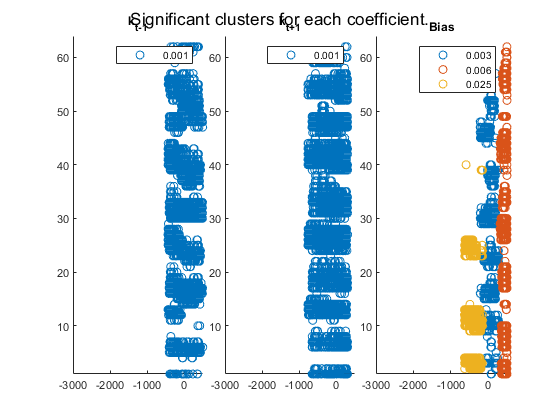

figure;
sgtitle('Significant clusters for each coefficient.')
tiledlayout(1, 3, 'TileSpacing', 'compact')


for current_beta = 1:size(mask, 3)
    clusters = unique(mask(:, :, current_beta))';
    clusters(clusters == 0) = []; % Remove 0, 0 is no significant cluster

    ax = nexttile;
    title(sprintf("%s", betas_names{current_beta}));

    hold on;
    xlim(epoch_size * 1000);
    ylim([1, size(mask, 1)]);

    this_beta_cluster_ps = {};

    for current_cluster = clusters
        cluster_indices = squeeze(mask(:, :, current_beta)) == current_cluster;
        [cluster_pos_x, cluster_pos_y] = find(cluster_indices');

        hold on;
        scatter(cluster_pos_x + (epoch_size(1) * 1000), cluster_pos_y);

        this_cluster_p = squeeze(cluster_p(:, :, current_beta));
        this_beta_cluster_ps{current_cluster} = string(max(this_cluster_p(cluster_indices)));
    end

    legend(this_beta_cluster_ps);
end